clc; close all; clear all;

global kappa m_ball g alpha_0
y_0 = 30*10^-2

y_0 = 0.3000

l = 180*10^-2

l = 1.8000

alpha_0 = 5

alpha_0 = 5

v_0 = 6.1

v_0 = 6.1000

g = 9.81

g = 9.8100

c_w = 0.47

c_w = 0.4700

roh = 1.2

roh = 1.2000

s_becher = 0.5*10^-2 

s_becher = 0.0050

d_becher = 9.5*10^-2

d_becher = 0.0950

d_ball = 50

d_ball = 50

t = 1

t = 1


m_ball = 20

m_ball = 20


% Luftwiderstandskonstante
kappa = roh*(d_ball*10^-3)^2*pi*c_w/8

kappa = 5.5371e-04

fun=@(t,y)[y(2);-kappa*sqrt(y(2)^2+y(4)^2)*y(2)/(m_ball*10^-3);y(4);kappa*sqrt(y(2)^2+y(4)^2)*y(4)/(m_ball*10^-3)-g];

x0=0;      %supply x(t0)
x0prime=v_0*cosd(alpha_0); %supply x'(t0)
y0=y_0;      %supply y(t0)
y0prime=v_0*sind(alpha_0); %supply y'(t0)
Y0=[x0; x0prime; y0; y0prime];

tspan = [0 t]

tspan =      0     1



[T,Y]=ode45(fun,tspan,Y0);

m = Y(Y(:,3)>=0,:)

m =          0    6.0768    0.3000    0.5317
    0.0001    6.0768    0.3000    0.5316
    0.0001    6.0768    0.3000    0.5315
    0.0002    6.0768    0.3000    0.5314
    0.0002    6.0768    0.3000    0.5313
    0.0005    6.0767    0.3000    0.5309
    0.0007    6.0767    0.3001    0.5305
    0.0010    6.0766    0.3001    0.5301
    0.0012    6.0766    0.3001    0.5297
    0.0025    6.0764    0.3002    0.5277


Y = Y(1:size(m,1)+1,:)

Y =          0    6.0768    0.3000    0.5317
    0.0001    6.0768    0.3000    0.5316
    0.0001    6.0768    0.3000    0.5315
    0.0002    6.0768    0.3000    0.5314
    0.0002    6.0768    0.3000    0.5313
    0.0005    6.0767    0.3000    0.5309
    0.0007    6.0767    0.3001    0.5305
    0.0010    6.0766    0.3001    0.5301
    0.0012    6.0766    0.3001    0.5297
    0.0025    6.0764    0.3002    0.5277


T = T(1:size(Y,1),:)

T =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0002
    0.0002
    0.0004


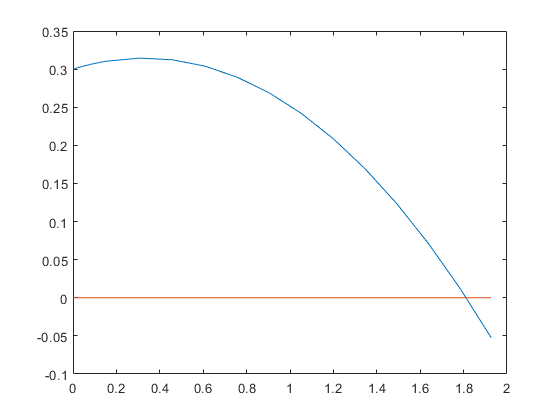


plot(Y(:,1),Y(:,3)) %plot x y
hold on
plot(Y(:,1),zeros(size(T,1),1))
hold off